## Parameters

on_GPU = false;
T = 40; % sec
N = 200; % number of neurons 200
input_Hz = 50; % Hz
conn_prob_input2E = 0.1; % a.u.
conn_strength_input2E = 1; % a.u.
conn_prob_E2E = 0.25; % a.u.
conn_strength_E2E = 1; % a.u.
STDP_learning_rate_E2E = 1; % a.u. (STDP)

plasticity_type = "rbSTDP";

plot_synapses = false;
plot_Vm = false;
plot_spikes = false;
plot_refractoriness = false;
plot_weights = true;
plot_Hz = true;
plot_stimulation = true;
plot_STDP_traces = false;
plot_resource_pool = true;
plot_digraph = true;
plot_non_potentiable = true;
plot_dependence = false;

## Run a single EI pool with

samples = 8;
pool_single = cell(samples);

parfor n=1:samples
    % Set up
    tic
    pool_single{n} = RB_STDP_EI_pool( ...
        T, ...
        N, ...
        on_GPU, ...
        conn_prob_input2E, ...
        conn_strength_input2E, ...
        conn_prob_E2E, ...
        conn_strength_E2E, ...
        plasticity_type, ...
        plot_synapses, ...
        plot_Vm, ...
        plot_spikes, ...
        plot_refractoriness, ...
        plot_weights, ...
        plot_Hz, ...
        plot_stimulation, ...
        plot_STDP_traces, ...
        plot_resource_pool, ...
        plot_digraph, ...
        plot_non_potentiable, ...
        plot_dependence ...
        );
    pool_single{n}.set_input( ...
        input_Hz ...
        );
    toc
    % Run
    tStart = tic;
    pool_single{n}.run( ...
        false, ... % plot_during
        STDP_learning_rate_E2E ...
        );
    tEnd = toc(tStart);
    fprintf( ...
        'Elapsed time is %d minutes and %f seconds\n', ...
        floor(tEnd/60), ...
        rem(tEnd,60) ...
        );
    % Finish
    tic
    pool_single{n}.finish()
    toc
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 6 7 8 9 11 13 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.



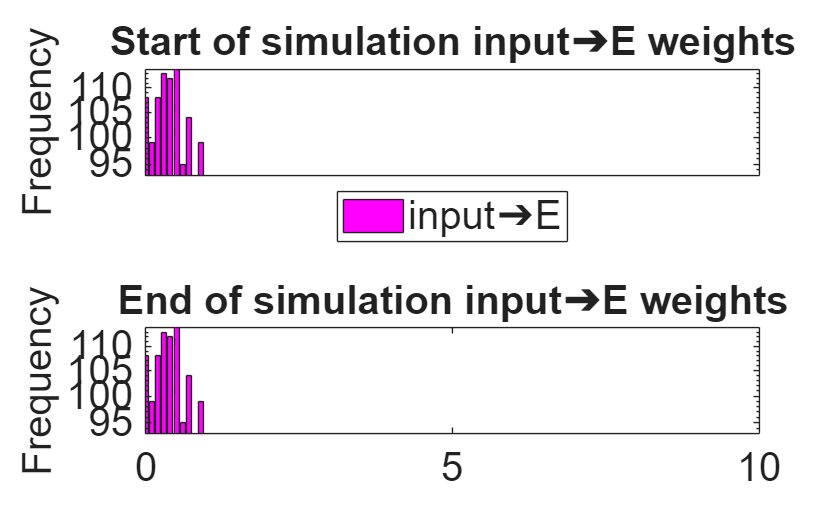

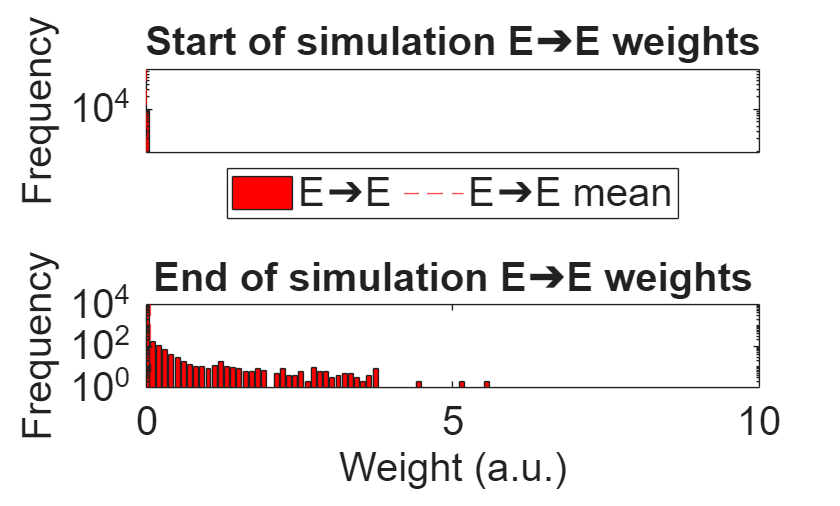

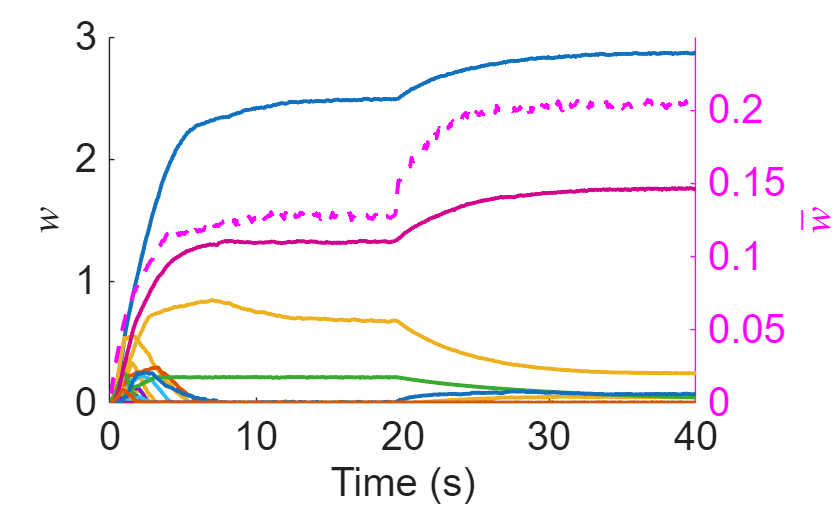

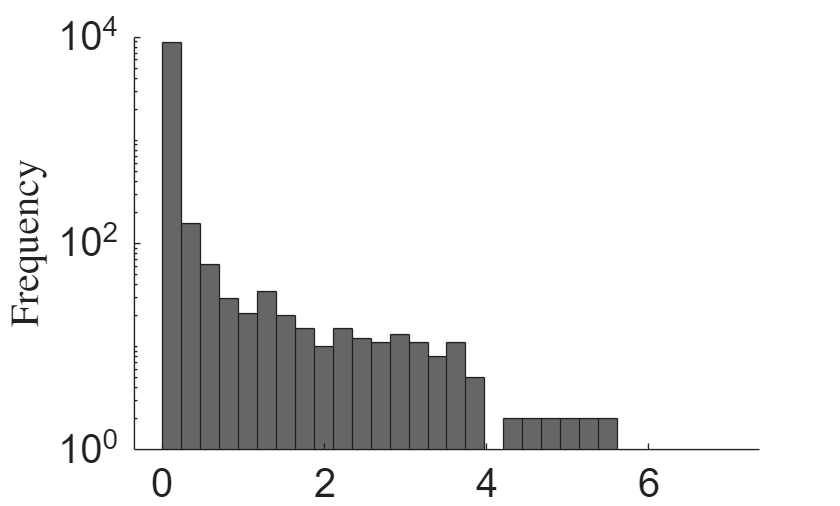

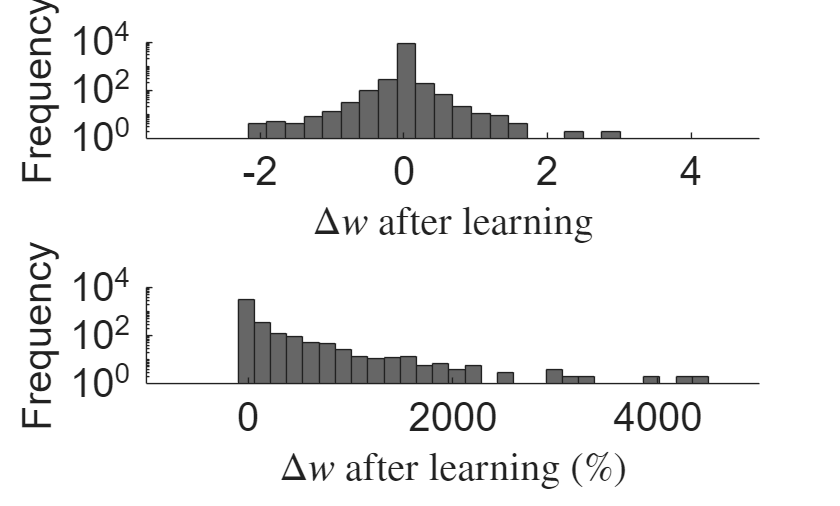

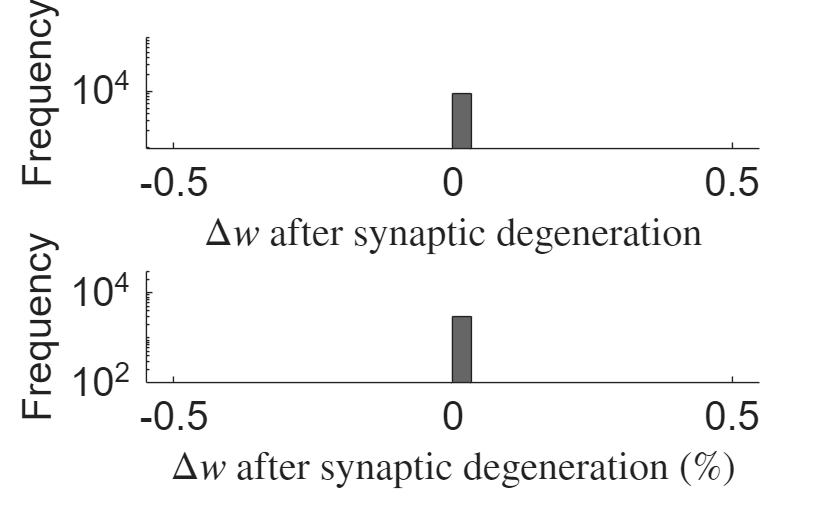

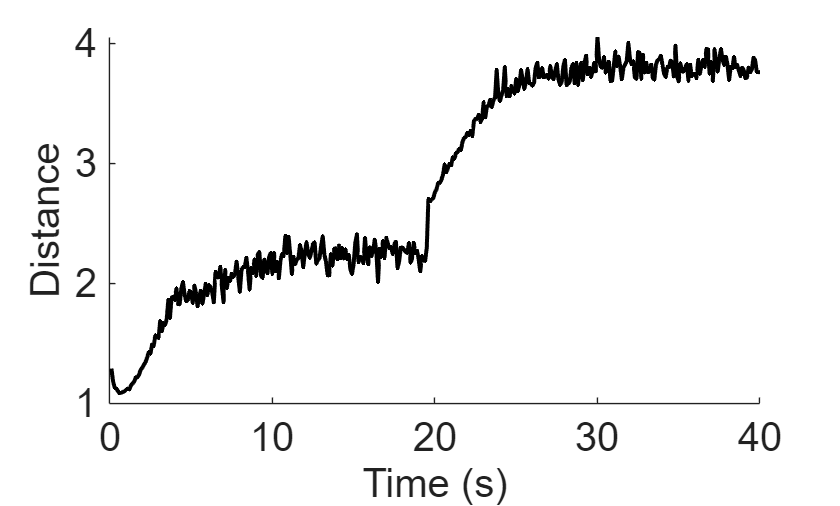

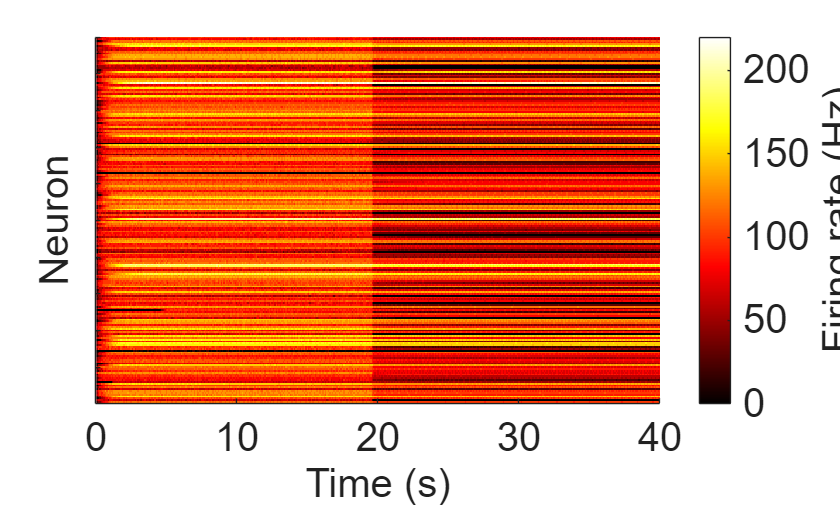

% Plot
tic
pool_single{4}.fontsize = 20;
pool_single{4}.plot( ... % 4
    true ... % export
    )

toc

Elapsed time is 64.858306 seconds.
